% ID number: 2021200687
% Name:      唐金峰
% Date:      Nov 23, 2021

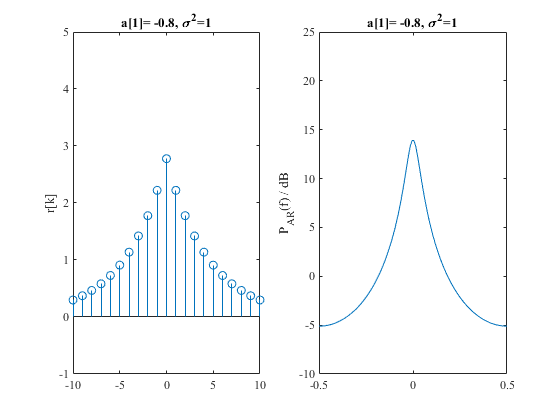

% AR(1) 模型
AR1 = arima(1,0,0);
AR1.Constant = 0;
AR1.Variance = 1;
AR1.AR = { -0.8};
rxx = zeros(11,1);
rxx(1) = AR1.Variance / (1- AR1.AR{1}^2);
for k = 1:length(rxx)-1
    rxx(k+1) = rxx(1) * (-1* AR1.AR{1})^k;
end
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-1 5])
title(['a[1]= ' num2str(AR1.AR{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
f = linspace(-1/2,1/2,100);
par = AR1.Variance./abs( 1 + AR1.AR{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
ylim([-10 25])
title(['a[1]= ' num2str(AR1.AR{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

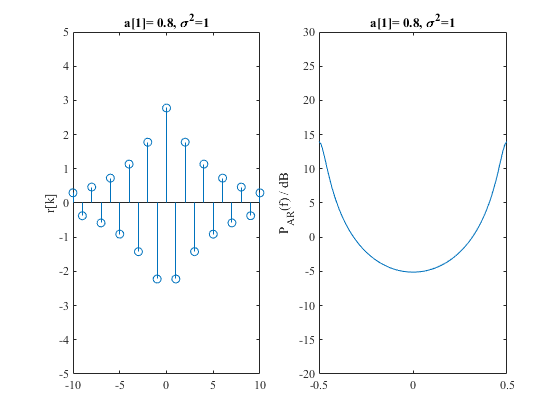

% AR(1) 模型
AR1.Constant = 0;
AR1.Variance = 1;
AR1.AR = { 0.8};
rxx(1) = AR1.Variance / (1- AR1.AR{1}^2);
for k = 1:length(rxx)-1
    rxx(k+1) = rxx(1) * (-1* AR1.AR{1})^k;
end
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-5 5])
title(['a[1]= ' num2str(AR1.AR{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = AR1.Variance./abs( 1 + AR1.AR{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
ylim([-20 30])
title(['a[1]= ' num2str(AR1.AR{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

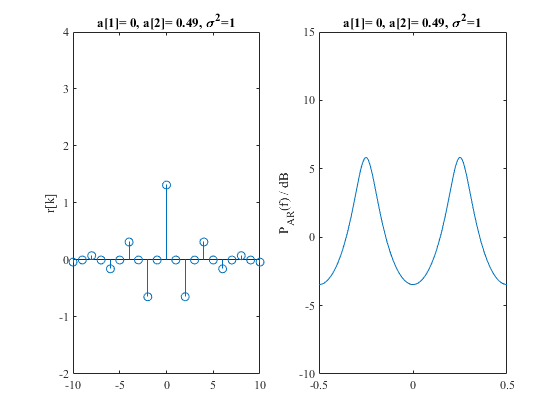

% AR(2) 模型
AR2 = arima(2,0,0);
AR2.Constant = 0;
AR2.Variance = 1;
AR2.AR = { 0.0 0.49};
r = sqrt(AR2.AR{2});
f0 = 1/(2*pi) *acos( ( AR2.AR{1}/(-2*r) ) );
phi = atan( (1-r^2)/(1+r^2)*cot(2*pi*f0) );
for k = 0 :length(rxx)-1
    rxx(k+1) = AR2.Variance*(1+r^2)/(1-r^2)...
        *sqrt( 1+ ((1-r^2)/(1+r^2))^2*cot(2*pi*f0)^2 ) ...
        /(1-2*r^2*cos(4*pi*f0) + r^4) ...
        *r^k*cos(2*pi*f0*k-phi);
end
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-2 4])
title(['a[1]= ' num2str(AR2.AR{1}) ', a[2]= ' num2str(AR2.AR{2}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = AR2.Variance./abs( 1 + AR2.AR{1}*exp(-1j*2*pi*f)...
   + AR2.AR{2}*exp(-1j*4*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
ylim([-10 15])
title(['a[1]= ' num2str(AR2.AR{1}) ', a[2]= ' num2str(AR2.AR{2}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

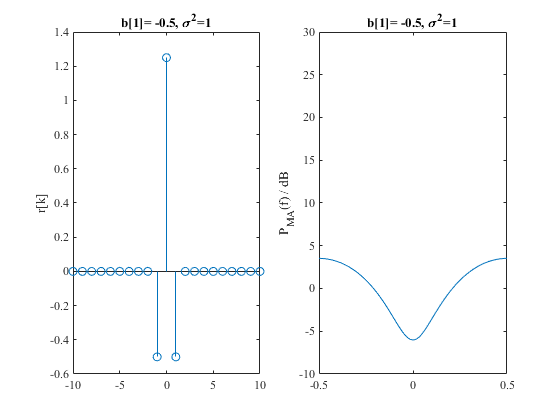

% MA(1) 模型
MA1 = arima(0,0,1);
MA1.Constant = 0;
MA1.Variance = 1;
MA1.MA = { -0.5};
rxx = [1+MA1.MA{1}^2; MA1.MA{1};zeros(length(rxx)-2,1)]*MA1.Variance;
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-0.6 1.4])
title(['b[1]= ' num2str(MA1.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = MA1.Variance.*abs( 1 + MA1.MA{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{MA}(f) / dB'
ylim([-10 30])
title(['b[1]= ' num2str(MA1.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

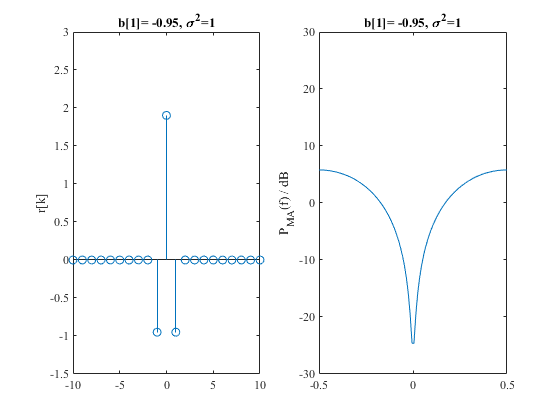

% MA(1) 模型
MA1.Constant = 0;
MA1.Variance = 1;
MA1.MA = { -0.95};
rxx = [1+MA1.MA{1}^2; MA1.MA{1};zeros(length(rxx)-2,1)]*MA1.Variance;
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-1.5 3])
title(['b[1]= ' num2str(MA1.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = MA1.Variance.*abs( 1 + MA1.MA{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{MA}(f) / dB'
ylim([-30 30])
title(['b[1]= ' num2str(MA1.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

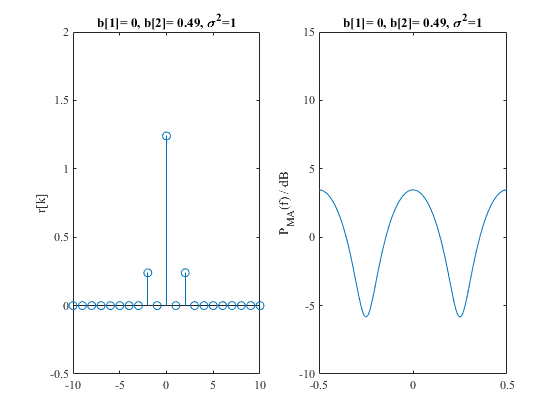

% MA(2) 模型
MA2 = arima(0,0,2);
MA2.Constant = 0;
MA2.Variance = 1;
MA2.MA = { 0 0.49};
rxx = [1+MA2.MA{1}^2+MA2.MA{2}^2;
    MA2.MA{1}*MA2.MA{2};
    MA2.MA{2}^2;
    zeros(length(rxx)-3,1)]*MA2.Variance;
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-0.5 2])
title(['b[1]= ' num2str(MA2.MA{1}) ', b[2]= ' num2str(MA2.MA{2}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = MA2.Variance.*abs( 1 + MA2.MA{1}*exp(-1j*2*pi*f) + ...
    MA2.MA{2}*exp(-1j*4*pi*f)).^2;
plot(f, pow2db(par))
ylabel 'P_{MA}(f) / dB'
ylim([-10 15])
title(['b[1]= ' num2str(MA2.MA{1}) ', b[2]= ' num2str(MA2.MA{2}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

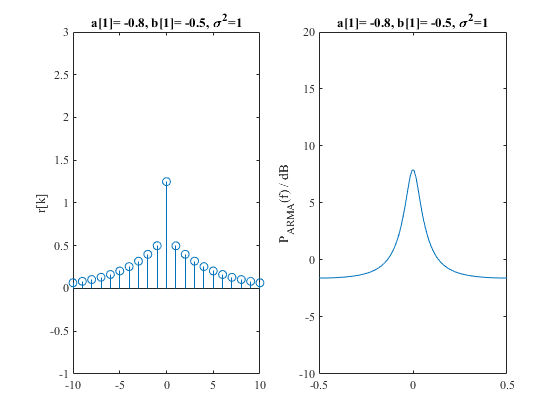

% ARMA(1,1) 模型
ARMA = arima(1,0,1);
ARMA.Constant = 0;
ARMA.Variance = 1;
ARMA.AR = { -0.8};
ARMA.MA = { -0.5};
rxx(1) = ARMA.Variance*(1+ ARMA.MA{1}^2- 2*ARMA.MA{1}*ARMA.AR{1})/(1- ARMA.AR{1}^2);
rxx(2) = ARMA.Variance*( (1- ARMA.MA{1}*ARMA.AR{1})* (ARMA.MA{1}-ARMA.AR{1}) ) ...
    /(1- ARMA.AR{1}^2);
for k = 2:length(rxx)-1
    rxx(k+1) = rxx(k) * (-1* ARMA.AR{1});
end
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-1 3])
title(['a[1]= ' num2str(ARMA.AR{1}) ', b[1]= ' num2str(ARMA.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = ARMA.Variance*abs( 1 + ARMA.MA{1}*exp(-1j*2*pi*f) ).^2 ./...
    abs( 1 + ARMA.AR{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{ARMA}(f) / dB'
ylim([-10 20])
title(['a[1]= ' num2str(ARMA.AR{1}) ', b[1]= ' num2str(ARMA.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')

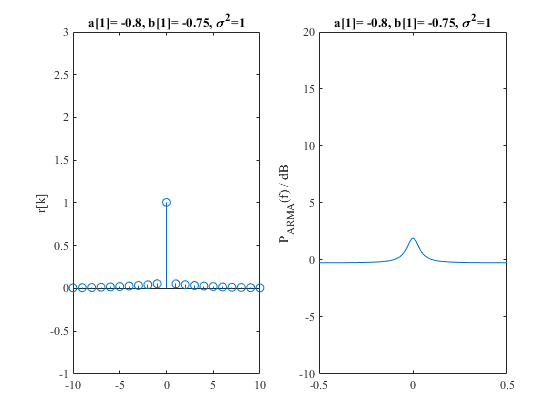

% ARMA(1,1) 模型
ARMA = arima(1,0,1);
ARMA.Constant = 0;
ARMA.Variance = 1;
ARMA.AR = { -0.8};
ARMA.MA = { -0.75};
rxx(1) = ARMA.Variance*(1+ ARMA.MA{1}^2- 2*ARMA.MA{1}*ARMA.AR{1})/(1- ARMA.AR{1}^2);
rxx(2) = ARMA.Variance*( (1- ARMA.MA{1}*ARMA.AR{1})* (ARMA.MA{1}-ARMA.AR{1}) ) ...
    /(1- ARMA.AR{1}^2);
for k = 2:length(rxx)-1
    rxx(k+1) = rxx(k) * (-1* ARMA.AR{1});
end
rxx_complex = [conj(flip(rxx(2:end))); rxx];
figure
subplot(121)
stem(-length(rxx)+1:length(rxx)-1,rxx_complex)
ylabel 'r[k]'
ylim([-1 3])
title(['a[1]= ' num2str(ARMA.AR{1}) ', b[1]= ' num2str(ARMA.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')
subplot(122)
par = ARMA.Variance*abs( 1 + ARMA.MA{1}*exp(-1j*2*pi*f) ).^2 ./...
    abs( 1 + ARMA.AR{1}*exp(-1j*2*pi*f) ).^2;
plot(f, pow2db(par))
ylabel 'P_{ARMA}(f) / dB'
ylim([-10 20])
title(['a[1]= ' num2str(ARMA.AR{1}) ', b[1]= ' num2str(ARMA.MA{1}) ', \sigma^2=1'])
get(gca,'fontname');
set(gca,'fontname','Times New Roman')